clc
clear

## **Generate a DOGPUP mesh**

*Meshing is facilitated by the iso2mesh toolbox, see: *[*https://iso2mesh.sourceforge.net/cgi-bin/index.cgi*](https://iso2mesh.sourceforge.net/cgi-bin/index.cgi)

[node,~,elem] = meshabox([0 0 0],[60 30 60],1.2); % 60 x 30 x 60 mm mesh

generating tetrahedral mesh from closed surfaces ...
creating volumetric mesh from a surface mesh ...
volume mesh generation is complete


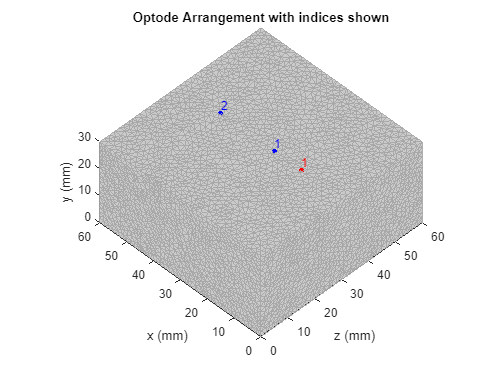

elem = elem(:,1:4);
[node,elem] = sortmesh([],node,elem); % optimise node and element ordering

% initialise DOGPUP mesh
mua = 0.008; % absorption (mm^-1)
musp = 0.9; % reduced scattering (mm^-1)
nr = 1.4; % refractive index
mesh = dMesh(node,elem,nr,[mua musp]);

% initialise optodes
% Source stats
dt = 50e-12;
t = 0:dt:(140*dt);
% Source TPSF
avgPow = 1e3;
fwhm = 250e-12;
time_dev = fwhm./(2*sqrt(2*log(2)));
tpsf = exp(-((t-6.*time_dev).^2)./(2.*(time_dev).^2));
Nf = 30; % number of Fourier series coefficients for decomposition

% initialise DOGPUP optode object
optode = dOptode([15 65 30],[25 35 30; 45 35 30],[1 1; 1 2],avgPow,tpsf,t,Nf);
mesh = add_optode(mesh,optode);

figure
plotdmesh_snd(mesh,0.9,true)
title('Optode Arrangement with indices shown')

## Generate Forward data

Simulation of the fluence is done in the FD by truncated Fourier series decomposion see: [https://doi.org/10.1364/josaa.37.000182](https://doi.org/10.1364/josaa.37.000182)

% get fluence and boundary data
[phi,data_fc] = flu_solve(mesh,true);


solving for fluence...done!
detection generated!


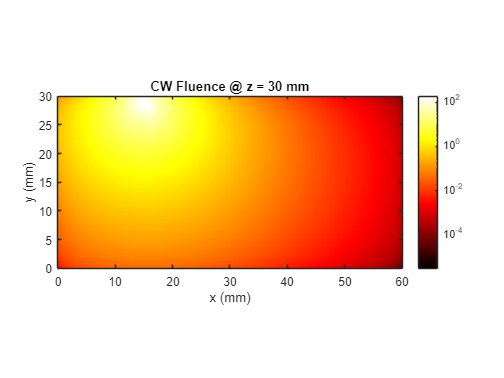


% plot log CW fluence
phi_plot = real(phi(:,1));

figure
plotfun_slice(mesh,phi_plot,hot,'z=30')
title('CW Fluence @ z = 30 mm')
set(gca,'ColorScale','log')
colorbar

TD data can be retrieved by using fd2td or fd2tg which transforms from Fourier coefficients to the full time domain or time gates respectively

See: [https://doi.org/10.3390/app9245468](https://doi.org/10.3390/app9245468) for more info on gated datatypes

f = optode.fAxis; % freq axis

% define gaussian time gates as our gating function
gateSize = 200e-12/(2*sqrt(2*log(2)));
gateStart = 0.3e-9;
gatePeriod = 6.5e-9;
gates = zeros(round(gatePeriod/gateSize),length(t));
for i = 1:size(gates,1)
    gates(i,:) = exp(-(t-(gateStart+(i-1).*gateSize)).^2./(2.*gateSize.^2));
end

g_t = gateStart:gateSize:(gateStart+gatePeriod); % gate mid points
gates_fc = td2fc(gates,f,t,2); % Fourier coefficients of gates

data_td = fc2td(data_fc,f,t,2); % full time domain
data_tg = fc2tg(data_fc,gates_fc,f,numel(t),2); % time gates


Note that the gated dataype is more stable for low fluence

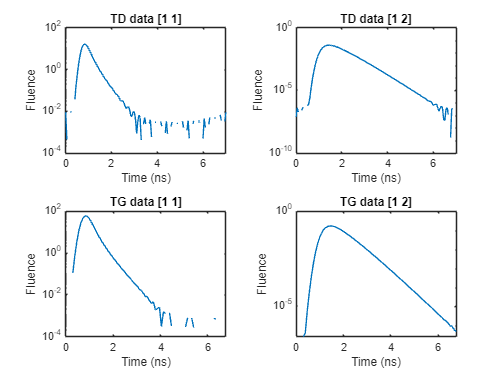

% plot TD and TG data
figure
tiledlayout(2,2)
h(1) = nexttile;
plt_data = data_td(1,:);
plt_data(plt_data<0) = NaN;
plot(t.*1e9,plt_data)
xlabel('Time (ns)')
ylabel('Fluence')
title('TD data [1 1]')

h(2) = nexttile;
plt_data = data_td(2,:);
plt_data(plt_data<0) = NaN;
plot(t.*1e9,plt_data)
xlabel('Time (ns)')
ylabel('Fluence')
title('TD data [1 2]')

h(3) = nexttile;
plt_data = data_tg(1,:);
plt_data(plt_data<0) = NaN;
plot(g_t.*1e9,plt_data)
xlabel('Time (ns)')
ylabel('Fluence')
title('TG data [1 1]')

h(4) = nexttile;
plt_data = data_tg(2,:);
plt_data(plt_data<0) = NaN;
plot(g_t.*1e9,plt_data)
xlabel('Time (ns)')
ylabel('Fluence')
title('TG data [1 2]')

set(h,'YScale','log')

## Generate measurement sensitvity a.k.a. the Jacobian

Sensitivity is generated in the FD using the adjoint method, output is complex

% first define voxel grid for sensitivity
dxyz = 3;
x = -dxyz:dxyz:(60+dxyz);
y = -dxyz:dxyz:(30+dxyz);
z = -dxyz:dxyz:(60+dxyz);
mesh = mesh2grid(mesh,x,y,z); % generates interpolation matrices etc.

% generate sensitvities
J = J_complex(mesh,phi,[],true);


solving for adjoint fluence...done!

generating complex absorption jacobian...done!


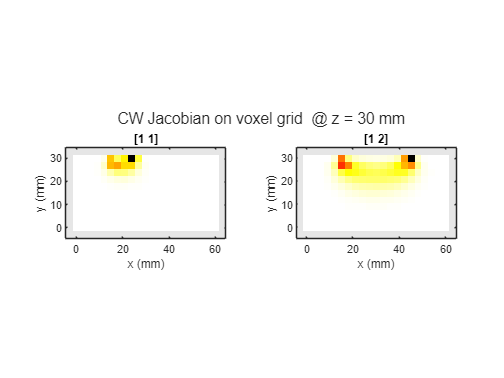

J_CW = squeeze(J(:,1,:)./data_fc(:,1)); % rytov normalised for log err

J_CWinterp = (mesh.g2m*J_CW.').'; % interpolate to mesh

% plotting on voxel grid and mesh
figure
tl = tiledlayout(1,2);
nexttile
plotfun_grid(mesh,J_CW(1,:).',hot,'z=30')
title('[1 1]')
nexttile
plotfun_grid(mesh,J_CW(2,:).',hot,'z=30')
title('[1 2]')

title(tl,'CW Jacobian on voxel grid  @ z = 30 mm')

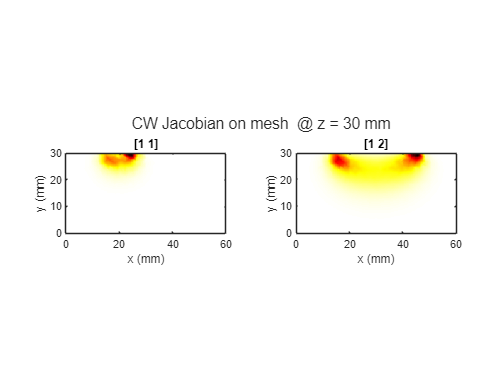


figure
tl = tiledlayout(1,2);
nexttile
plotfun_slice(mesh,J_CWinterp(1,:).',hot,'z=30')
title('[1 1]')
nexttile
plotfun_slice(mesh,J_CWinterp(2,:).',hot,'z=30')
title('[1 2]')

title(tl,'CW Jacobian on mesh  @ z = 30 mm')

## Generate gated sensitvity

TD sensitvity can be retrieved by using fd2td or fd2tg which transforms from Fourier coefficients to the full time domain or time gates respectively.

Note the change in depth sensitvity between early and late gates

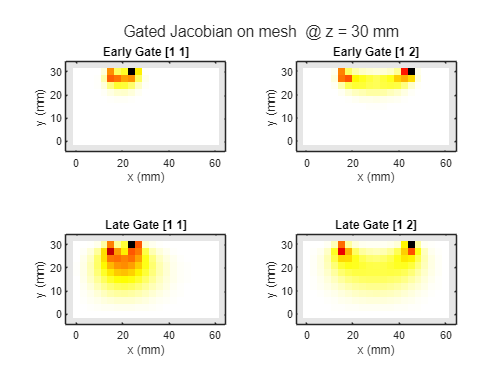

% Gated data sensitivity
J_TG = fc2tg(J,gates_fc,f,numel(t),2);

% interpolate to mesh
J_TGinterp = pagemtimes(full(mesh.g2m),permute(J_TG,[3 1 2]));
J_TGinterp = permute(J_TGinterp,[2 3 1])./data_tg; % rytov normalised for log err

figure
tl = tiledlayout(2,2);
nexttile
plotfun_grid(mesh,squeeze(J_TG(1,10,:)),hot,'z=30')
title('Early Gate [1 1]')
nexttile
plotfun_grid(mesh,squeeze(J_TG(2,10,:)),hot,'z=30')
title('Early Gate [1 2]')
nexttile
plotfun_grid(mesh,squeeze(J_TG(1,40,:)),hot,'z=30')
title('Late Gate [1 1]')
nexttile
plotfun_grid(mesh,squeeze(J_TG(2,40,:)),hot,'z=30')
title('Late Gate [1 2]')

title(tl,'Gated Jacobian on mesh  @ z = 30 mm')

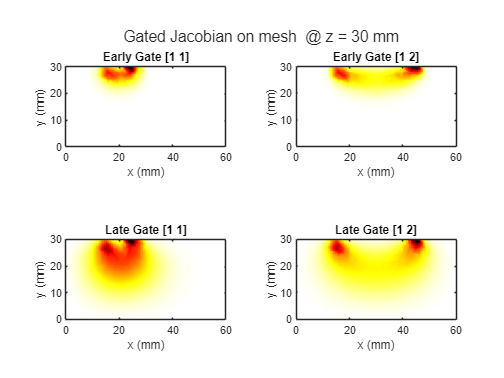


figure
tl = tiledlayout(2,2);
nexttile
plotfun_slice(mesh,squeeze(J_TGinterp(1,10,:)),hot,'z=30')
title('Early Gate [1 1]')
nexttile
plotfun_slice(mesh,squeeze(J_TGinterp(2,10,:)),hot,'z=30')
title('Early Gate [1 2]')
nexttile
plotfun_slice(mesh,squeeze(J_TGinterp(1,40,:)),hot,'z=30')
title('Late Gate [1 1]')
nexttile
plotfun_slice(mesh,squeeze(J_TGinterp(2,40,:)),hot,'z=30')
title('Late Gate [1 2]')

title(tl,'Gated Jacobian on mesh  @ z = 30 mm')